### Linear Algebra and Programming Skills

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Plotting

#### Learning Outcomes

On successful completion of this page readers will be able to:

- use MATLAB to produce line, scatter, surface and contour plots

- add axes labels, titles and legends to the plot axes;

- plot polygons;

- create image plots of pixel data;

- save plots to a file.

MATLAB comes with a number of functions that can be used to plot data. Here we will look at the most common plotting commands.

## Line plots

To plot a simple two-dimensional function we can use the `plot` command ([help page](https://uk.mathworks.com/help/matlab/ref/plot.html))

where `x co-ordinate array` and `y co-ordinate array` are $1\times n$ arrays.

**Example 1**

The MATLAB code below plots the function $y=x^2$. Enter it into the code cell below and run the live script.

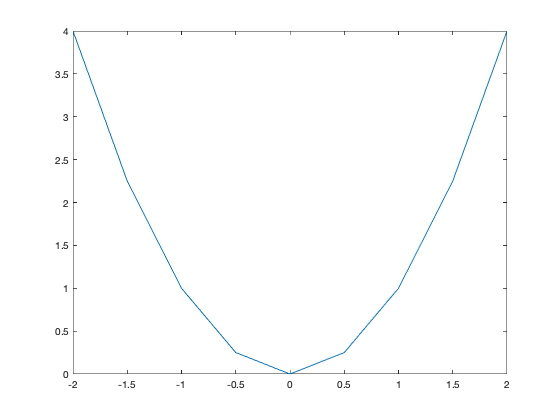

x = -2 : 0.5 : 2; % array of x co-ordinates
y = x .^ 2;         % array of y co-ordinates

plot(x, y)

You may notice that the line from the plot here is not very smooth. This is because the co-ordinate array `x` contains only 9 elements and MATLAB has drawn straight lines between each co-ordinate from the function $y=x^2$.  To produce a smooth plot simply decrease the `step` between each co-ordinate.

**Example 2**

Enter the following commands into the code cell below and run the live script.

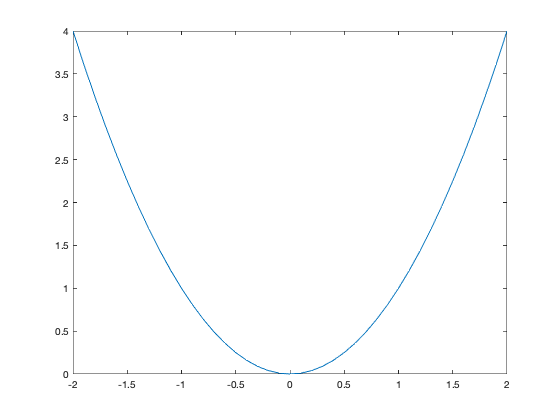

x = -2 : 0.1 : 2; % array of x co-ordinates
y = x .^ 2;         % array of y co-ordinates

plot(x, y)

### Plot styles

We can change the appearance of the line by specifying the `LineSpec` after the co-ordinates in the `plot` command. The `LineSpec` is a series of symbols that determine the ***colour***, ***line style*** and ***marker style*** used. 


$$\begin{array}{cl}
\textbf{Colour} & \textbf{Description} \\
\texttt{r} & \text{red} \\
\texttt{b} & \text{blue} \\
\texttt{k} & \text{black} \\
\texttt{g} & \text{green} \\
\texttt{y} & \text{yellow} \\
\texttt{c} & \text{cyan} \\
\texttt{m} & \text{magenta} \\
\texttt{w} & \text{white}
\end{array}$$
                   
$$\begin{array}{cl}
\textbf{Line style} & \textbf{Description} \\
 \texttt{-} & \text{solid line (default)}\\
\texttt{--} & \text{dashed line} \\
\texttt{:} & \text{dotted line} \\
\texttt{-.} & \text{dash-dot line}
\end{array}$$
             
$$\begin{array}{cl}
\textbf{Marker style} & \textbf{Description} \\
\texttt{o} & \text{circle} \\
\texttt{+} & \text{plus sign} \\
\texttt{*} & \text{asterisk} \\
\texttt{.} & \text{point} \\
\texttt{x} & \text{cross} \\
\texttt{s} & \text{square} \\
\texttt{d} & \text{diamond} \\
\texttt{\^{}} & \text{upward-pointing triangle} \\
\texttt{v} & \text{downward-pointing triangle} \\
\texttt{>} & \text{right-pointing triangle} \\
\texttt{<} & \text{left-pointing triangle}
\end{array}$$


**Example 3**

The MATLAB command below plots the function $y=x^2$ using a red line with circle marking each point (using the previously defined co-ordinate arrays `x` and `y`). Enter it into the code cell below and run the live script.

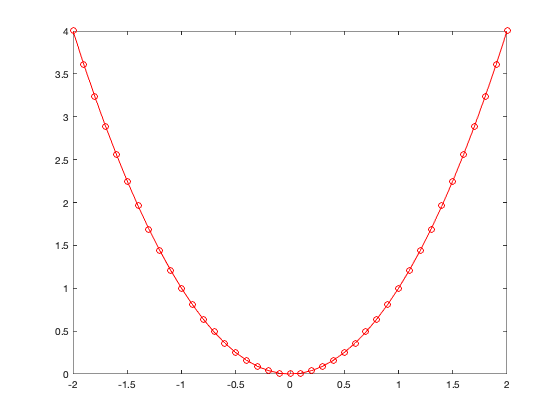

plot(x, y, 'r-o')

### Axis scale

The axis scale can be adjusted using the `axis` command ([help page](https://uk.mathworks.com/help/matlab/ref/axis.html))

where `xmin` and `xmax` are the minimum and maximum value along the $x$-axis (and similar for $y$). The `axis` command must come after any plot commands. 

**Example 4**

Enter the following command into the code cell below to change the axis limits on the plot from example 3 and run the live script.

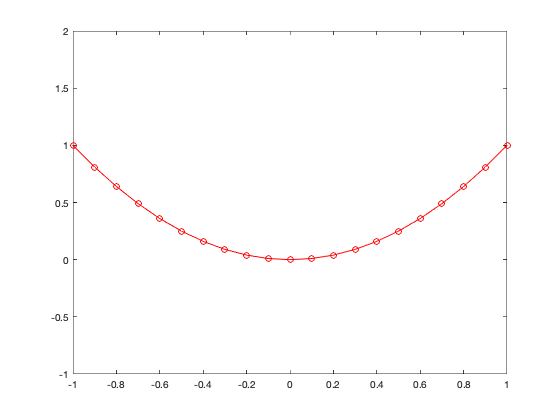

axis([ -1, 1, -1, 2 ])

There are other axis modes that can be utilised

### Axis labels and title

Axis labels and titles can be added to a plot using the `xlabel`, `ylabel` and `title` commands

Label and title commands must come after any plot commands.

**Example 5**

Enter the following commands into the code cell below to add axis labels and a title to the plot from example 4 and run the live script.

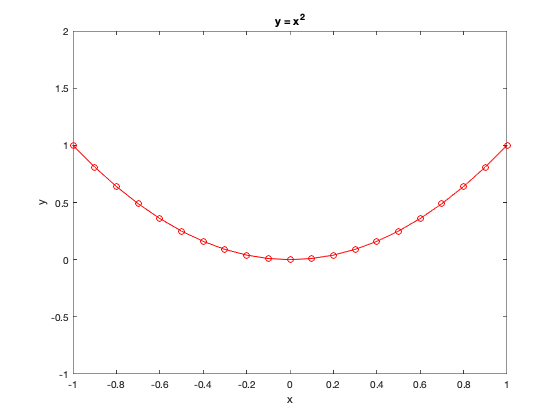

xlabel('x')
ylabel('y')
title('y = x^2')

**Example 6**

We can specify the font size used for axes labels and use LaTeX commands using `FontSize` and `Interpreter` options. Enter the following commands into the code cell below and run the live script.

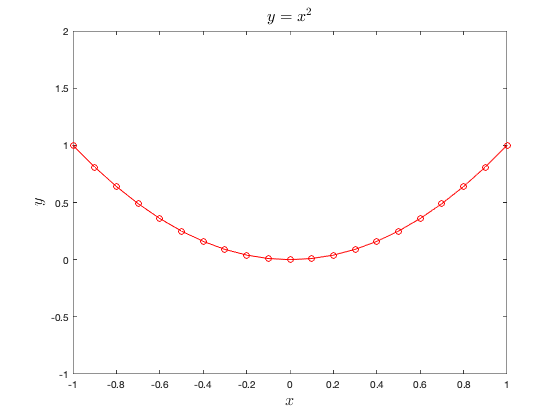

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')
title('$y = x^2$', 'FontSize', 16, 'Interpreter', 'latex')

### Exercise 1

1. Reproduce the plot of $y=\sin(x)$ over the domain $x\in[-2\pi, 2\pi]$ shown below.

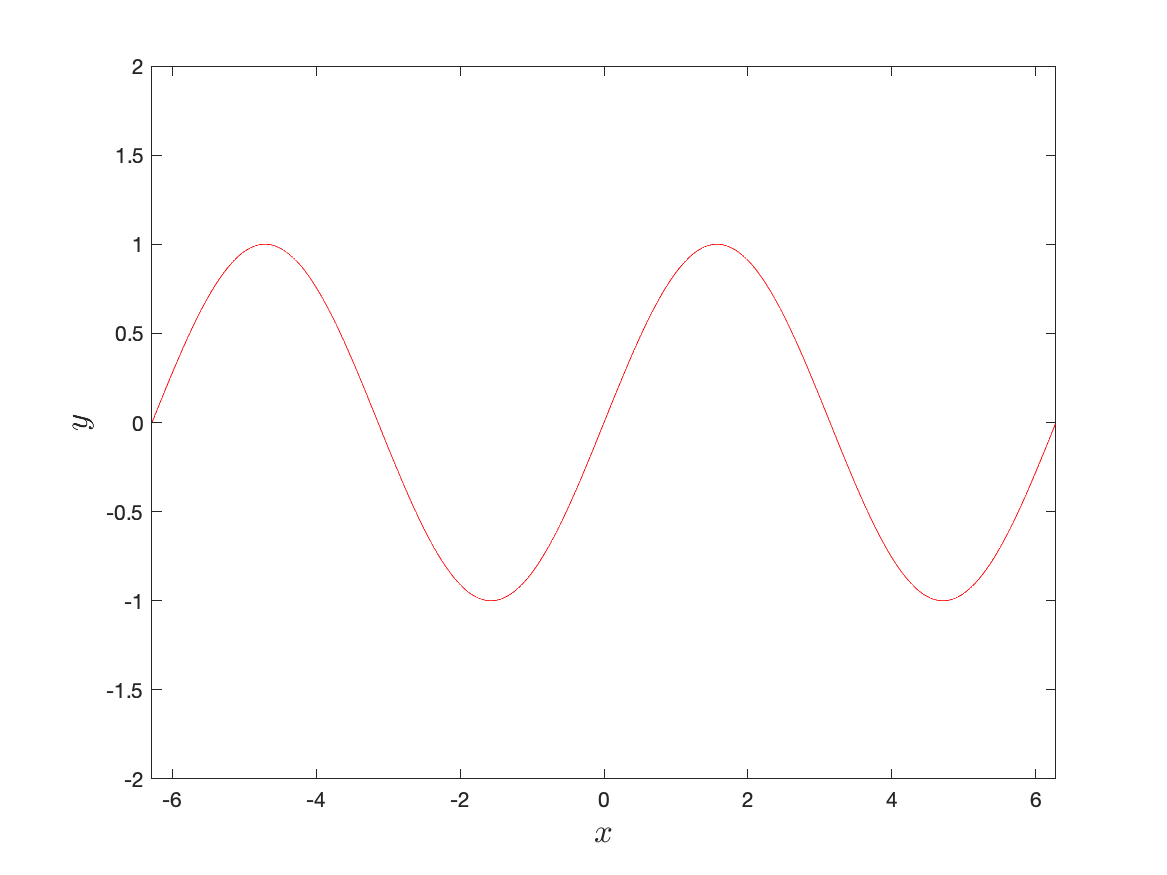

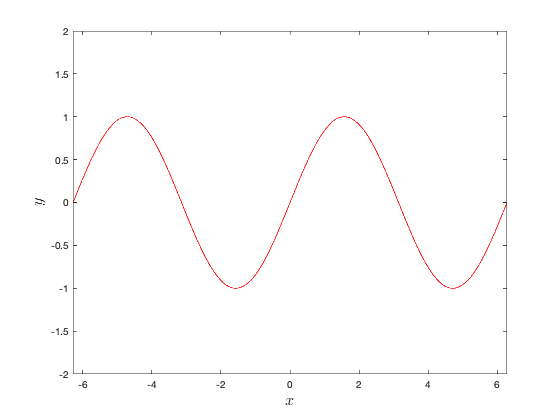

clear
x = -2*pi : 0.01 : 2*pi;

plot(x, sin(x), 'r')

axis([ -2*pi, 2*pi, -2, 2 ])

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

2. Produce a plot of the function $y = x^2 - 3x + 2$ over the domain $x\in[0, 10]$. 

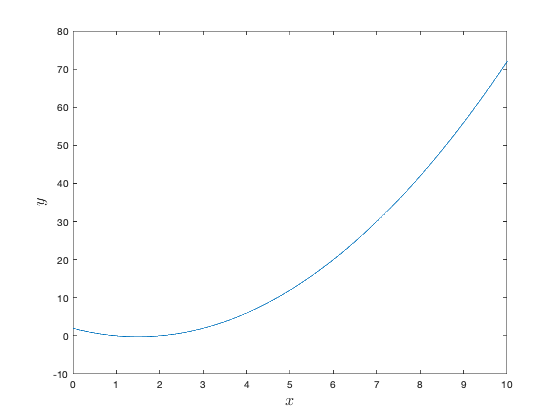

clear
x = 0 : 0.01 : 10;
y = x.^2 - 3*x + 2;

plot(x, y)

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

3. Produce a plot of the function $s = \frac{1}{t}$ over the domain $t\in[-1,1]$ using a green line.

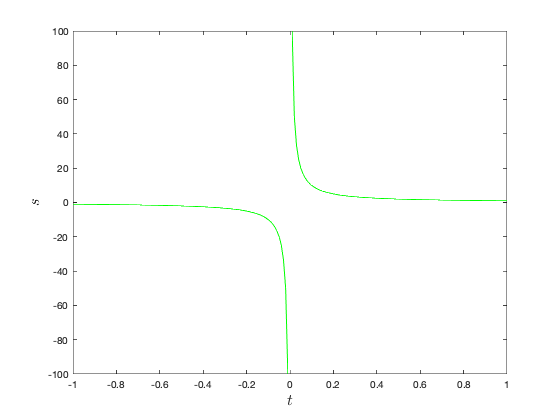

clear

t = -1 : 0.01 : 1;
s = 1./t;

plot(t, s, 'g-')

xlabel('$t$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$s$', 'FontSize', 16, 'Interpreter', 'latex')

## Multiple plots on the same axes

Whenever a plot command is used MATLAB will overwrite the previous plot. To suppress this and draw multiple plots on the same axes we use the `hold on` and `hold off` commands ([help page](https://uk.mathworks.com/help/matlab/ref/hold.html)), e.g.,

**Example 7**

Enter the following commands into the code cell below and run the live script.

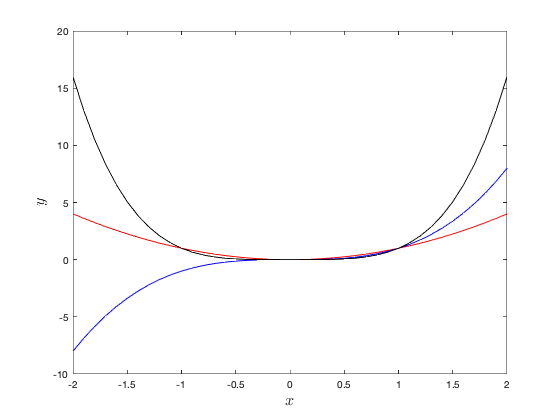

x = -2 : 0.1 : 2;
y1 = x.^2;          % first function
y2 = x.^3;          % second function
y3 = x.^4;          % third function

plot(x, y1, 'r-');  % first plot
hold on

plot(x, y2, 'b-');  % second plot
plot(x, y3, 'k-');  % third plot
hold off

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

### Legends

A legend can be added to a plot using the `legend` command ([help page](https://uk.mathworks.com/help/matlab/ref/legend.html)).

**Example 8**

Enter the following commands into the code cell below to add a legend to the plot from example 7 and run the live script.

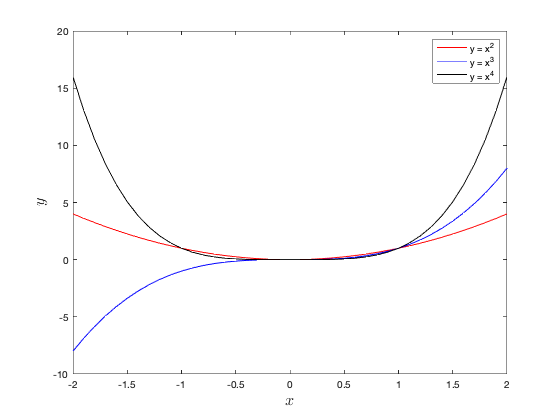

legend('y = x^2', 'y = x^3', 'y = x^4');

The font size and interpreter can be specified in the same was as it is done for axes labels. The placement of the legend can be specified using the `Location` option

where `placement` is one compass direction from  `'north', 'east', 'south'`, `'west'`, `'northeast'`, `'southeast'`, `'southwest'` or `'northwest'`.

**Example 9**

Enter the following command into the code cell below and run the live script.

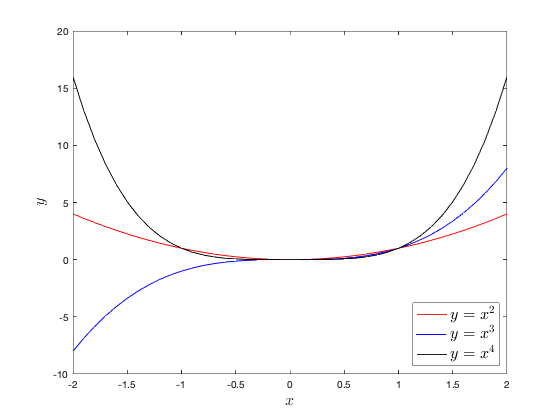

legend('$y = x^2$', '$y = x^3$', '$y = x^4$', ...
    'Location', 'southeast', 'FontSize', 16, 'Interpreter', 'latex')

## Saving a plot to file

The current figure can be saved to a file so that it can be inserted into a document using the `saveas` command ([help page](https://uk.mathworks.com/help/matlab/ref/saveas.html)).

Here `gcf` stands for 'get current figure' and `filename` should include the extension for the image. The common image formats such as `.png`, `.jpg`, `.pdf` etc are supported, however, to use the file in LaTeX or Word documents `.png` is preferred. 

**Example 10**

Enter the following command into the code cell below to save your plot from example 9 to a file with the name `myplot.png`. Open your newly created file to view the result.

saveas(gcf, 'myplot.png')

### Exercise 2

4. Reproduce this plot of $y=\sin(x)$ and $y=\cos(x)$ over the domain $x\in[-2\pi,2\pi]$ on the same set of axes.

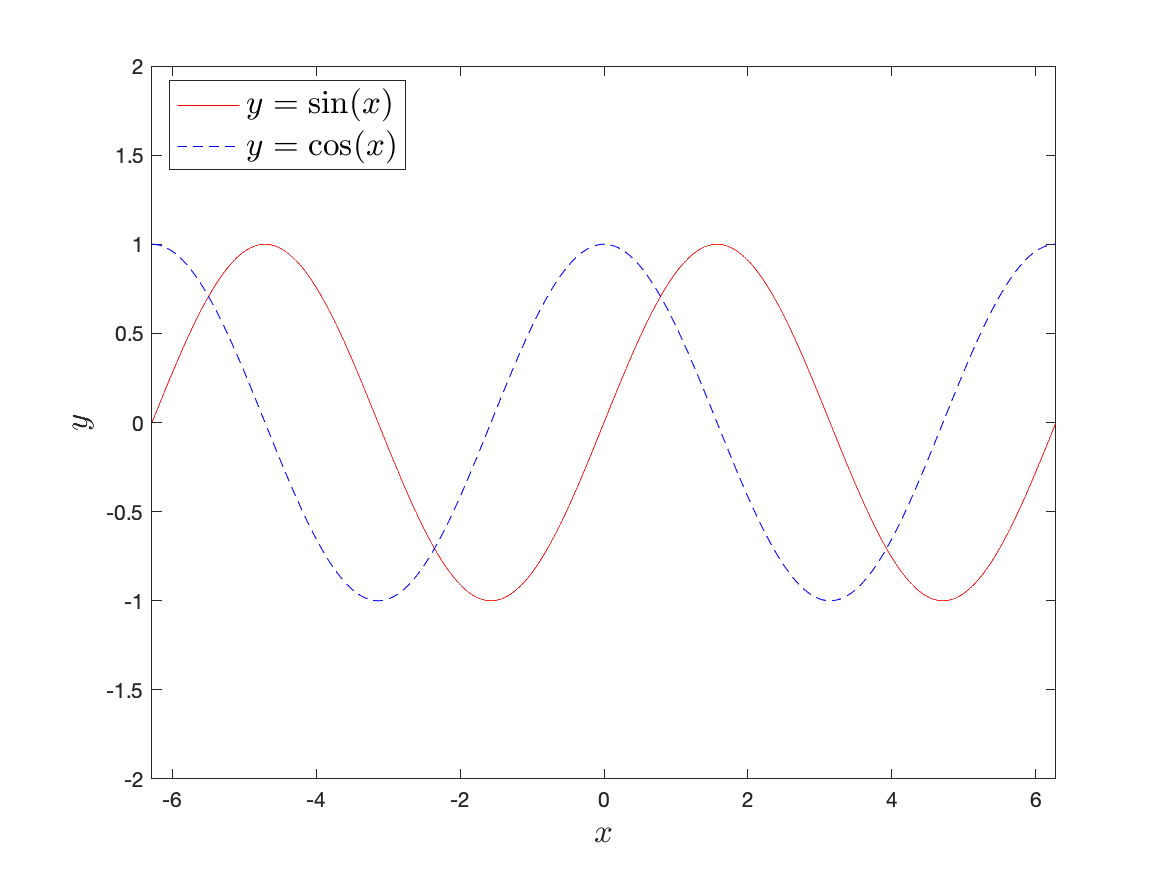

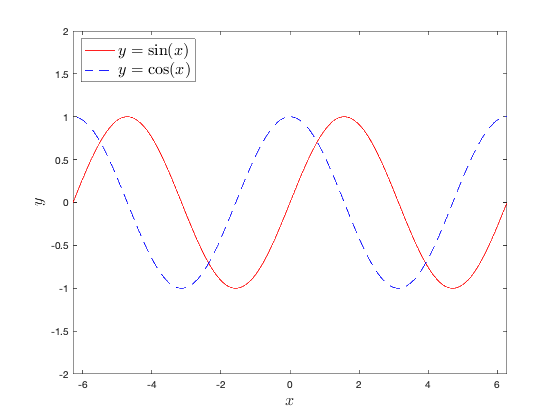

clear
x = -2*pi : 0.01 : 2*pi;

plot(x, sin(x), 'r')
hold on
plot(x, cos(x), 'b--')
hold off

axis([ -2*pi, 2*pi, -2, 2 ])

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

legend('$y=\sin(x)$', '$y=\cos(x)$', 'FontSize', 16, ...
    'Interpreter', 'latex', 'Location', 'northwest')

5. The points on a circle centred at $(c_x,c_y)$ with radius $r$ can be calculated using $(x,y) = (c_x,c_y) + r(\cos(\theta),\sin(\theta))$ for $\theta \in [0,2\pi]$. Plot four circles centred at $(5, 5)$ with radii $r=1, 2, 3, 4$. Use `axis` commands to display the circles in the correct aspect ratio (i.e., they look like circles and not ellipses).

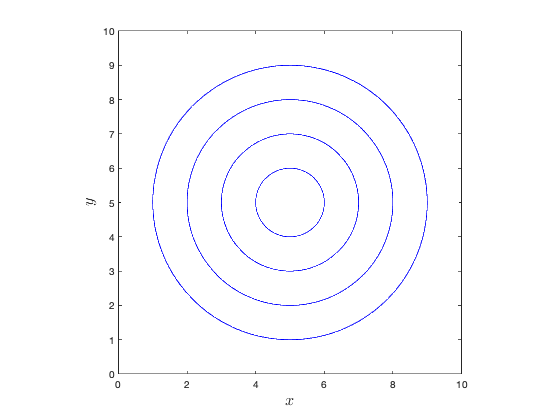

clear 
cx = 5;
cy = 5;
theta = 0 : 0.01 : 2*pi;

for r = 1 : 4
    x = cx + r*cos(theta);
    y = cy + r*sin(theta);
    plot(x, y, 'b-')
    hold on
end
hold off

axis([ 0, 10, 0, 10 ])
axis square

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

## Scatterplots

Scatterplots can be produced using the `scatter` command

The `marker style` is specified using the symbols explained in the Plot styles section.

**Example 11**

Enter the following commands into the code cell below and run the live script.

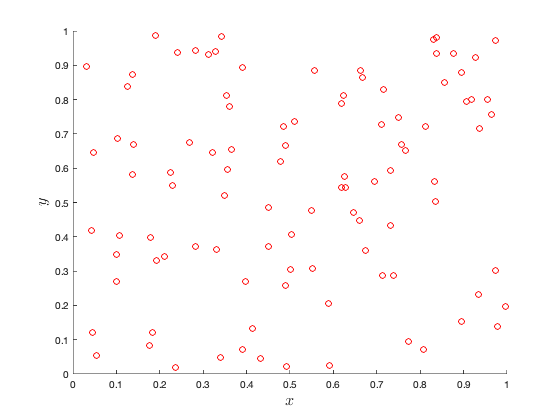

clear
x = rand(100, 1);   % 100x1 array of random numbers 
y = rand(100, 1);

scatter(x, y, 'r')

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

### Exercise 3

6) Reproduce the scatter plot shown below using the values of $x$ and $y$.

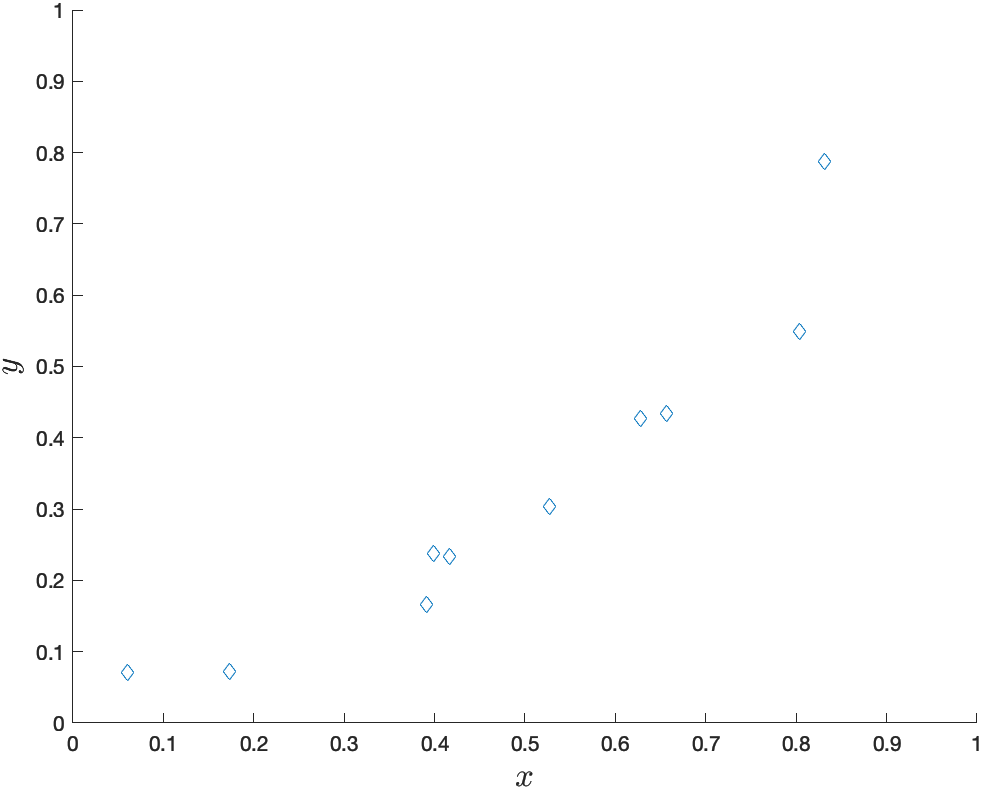

clear
x = [ 0.1734, 0.3909, 0.8314, 0.8034, 0.0605, 0.3993, 0.5269, 0.4168, 0.6569, 0.6280 ]';
y = [ 0.0717, 0.1665, 0.7881, 0.5486, 0.0702, 0.2382, 0.3031, 0.2341, 0.4335, 0.4265 ]';

scatter(x, y, 'd')

axis([ 0, 1, 0, 1 ])

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

7. We can calculate a line of best fit for this data using a linear regression model $y=\beta_0 + \beta_1 x$ where $\beta_0$ is the $y$-intercept and $\beta_1$ is the slope of the line. To determine $\beta_0$ and $\beta_1$ we need to solve the linear system

$\left(\matrix{y_1 \cr y_2 \cr \vdots \cr y_n}\right) = 
\left(\matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n}\right)
\left( \matrix{\beta_0 \cr \beta_1}\right)$.

Let $Y = \left(\matrix{y_1 \cr y_2 \cr \vdots \cr y_n}\right)$, $X = 
\left(\matrix{ 1 & x_1 \cr 1 & x_2 \cr \vdots & \vdots \cr 1 & x_n}\right)$ and $B = \left( \matrix{\beta_0 \cr \beta_1}\right)$ then we can use the MATLAB command `B = X \ Y` to solve for $B$. 

Calculate the line of best fit for the data from question 6 and add it to your scatter plot 

X = [ ones(length(x), 1), x ];
B = X \ y

B =    -0.0822
    0.8394


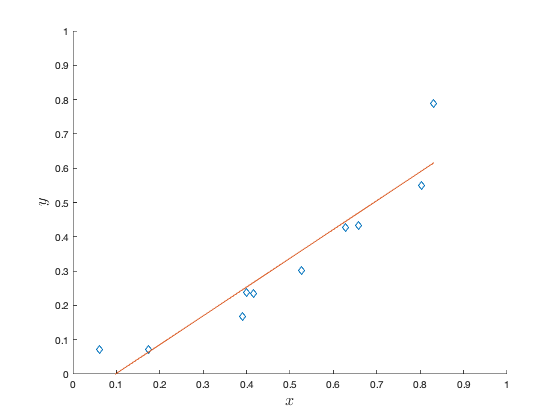


hold on
plot(x, B(1) + B(2)*x)
hold off

## Surface plots

Three-dimensional surface plots can be generated using the `surf` command ([help page](https://uk.mathworks.com/help/matlab/ref/surf.html)).

Where the co-ordinate matrix are $m\times n$ arrays. To produce a surface plot of the bivariate function $z=f(x,y)$ we require matrices containing the $x$ and $y$ coordinates of points in the domain. The `meshgrid` command ([help page](https://uk.mathworks.com/help/matlab/ref/meshgrid.html)) is useful for generating these.

**Example 12**

The MATLAB commands below generates two $4\times 6$ element matrices `X` and `Y` containing the co-ordinates of points in the domain$\{(x, y):x,y\in \mathbb{R}, 0 \leq x \leq 5, 0 \leq y \leq 6\}$ using an increment of 1 in the $x$ direction and 2 in the $y$ direction. Enter it into the code cell below and run the live script.

[X, Y] = meshgrid(0 : 5, 0 : 2 : 6);
disp(X)

     0     1     2     3     4     5
     0     1     2     3     4     5
     0     1     2     3     4     5
     0     1     2     3     4     5



disp(Y)

     0     0     0     0     0     0
     2     2     2     2     2     2
     4     4     4     4     4     4
     6     6     6     6     6     6



**Example 13**

The MATLAB code below produces a surface plot of the two-dimensional surface $z=\sin(x) + \cos(y)$ over the domain $x,y\in[0,4\pi]$. Enter it into the code cell below and run the live script.

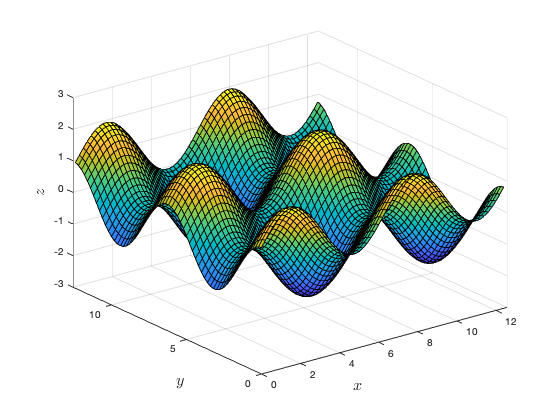

[X, Y] = meshgrid(0 : 0.2 : 4*pi, 0 : 0.2 : 4*pi);
Z = sin(X) + cos(Y);

surf(X, Y, Z)

axis([0, 4*pi, 0, 4*pi, -3, 3])

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')
zlabel('$z$', 'FontSize', 16, 'Interpreter', 'latex')

### View angle

With three-dimensional plots we can control the position of the viewpoint using the `view` command ([help page](https://uk.mathworks.com/help/matlab/ref/view.html))

where `azimuth` and `elevation` are the angles (in degrees) that specify the horizontal and vertical position of the viewpoint relative to the centre of view (see diagram below).

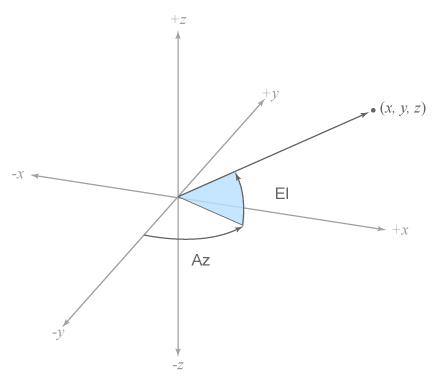

**Example 14**

The MATLAB command below changes the surface plot produced in example 13 so that it is viewed from the viewpoint with azimuth $15^\circ$ and elevation $45^\circ$. Enter it into the code cell below and run the live script.

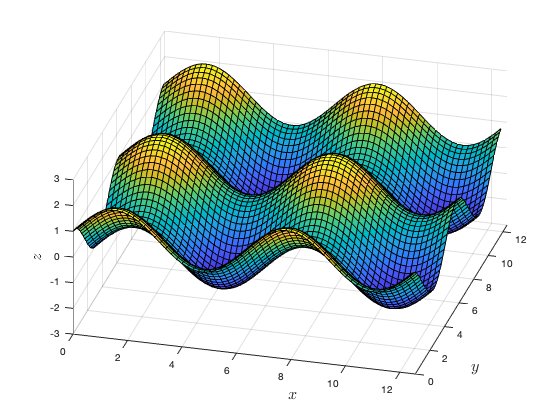

view(15, 45)

### Exercise 4

8. Reproduce the surface plot below of the function $z=\exp(-20((x - 0.5)^2 + (y - 0.5)^2))$ over the domain $x,y\in [0, 1]$.

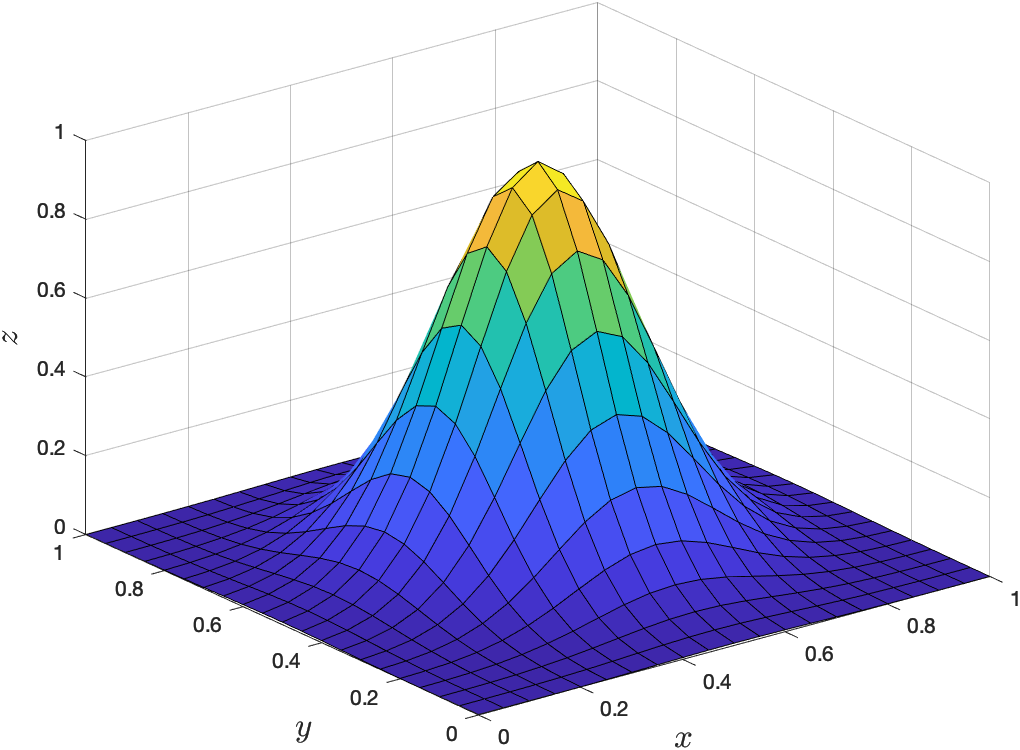

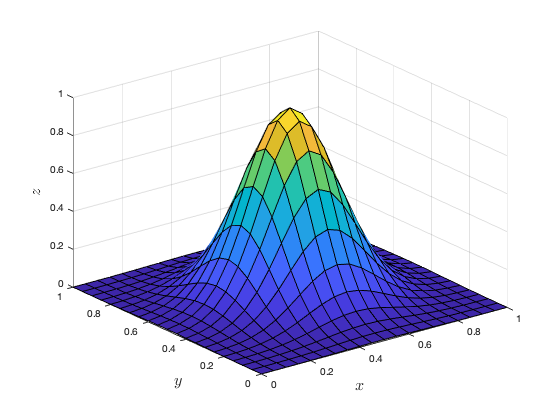

clear
[X, Y] = meshgrid(0 : 0.05 : 1, 0 : 0.05 : 1);
Z = exp(-20*((X - 0.5).^2 + (Y - 0.5).^2));

surf(X, Y, Z)

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')
zlabel('$z$', 'FontSize', 16, 'Interpreter', 'latex')

## Contour plots

Contour plots show points of equal value can be produced using the `contour` command ([help page](https://uk.mathworks.com/help/matlab/ref/contour.html))

**Example 15**

The code produces a contour plot of the same bivariate function used in example 13. Enter it into the code cell below and run the live script.

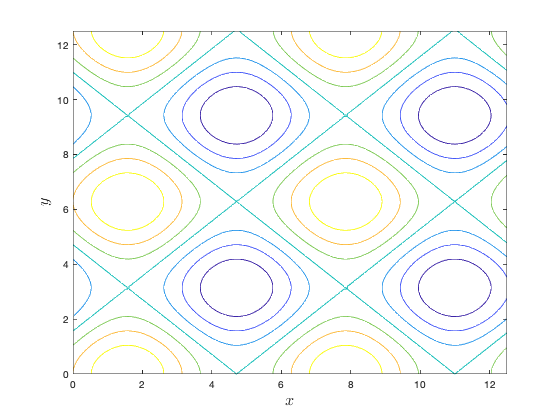

clear
[X, Y] = meshgrid(0 : 0.1 : 4*pi, 0 : 0.1 : 4*pi);
Z = sin(X) + cos(Y);

contour(X, Y, Z)

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

### Exercise 5

9. Produce a contour plot of the function $z = (z_1 - z_2)^2$ where $z_1 = \exp(-x^2-y^2)$ and $z_2=\exp(-(x-1)^2-(y-1)^2)$ over the domain $x,y \in [-2,3]$. 

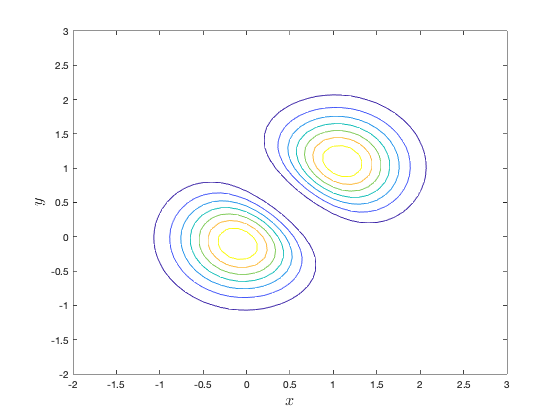

[X, Y] = meshgrid(-2 : 0.1 : 3, -2 : 0.1 : 3);
Z1 = exp(-X.^2 - Y.^2);
Z2 = exp(-(X - 1).^2 - (Y - 1).^2);
Z = (Z1 - Z2).^2;

contour(X, Y, Z)

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

## Plotting polygons

To plot a polygon on the current figure we can use the `patch` command ([help page](https://uk.mathworks.com/help/matlab/ref/patch.html))

The `vertex co-ordinates` arrays are $1\times n$ arrays containing the co-ordinates of the polygon vertices **in a continuous** direction around the vertices (an anti-clockwise direction is most commonly used). The `colour` can either be specified using the colours as explained in the Plot styles section or using a three-element array contain an RGB colour code (see the RGB colour model section below).

Since the `patch` command adds the polygon to the current figure we don't need to use `hold on` and `hold off` to plot multiple polygons. However, we need to clear the figure using the `clf` command before using `patch`. 

**Example 16**

Enter the following commands into the code cell below and run the live script.

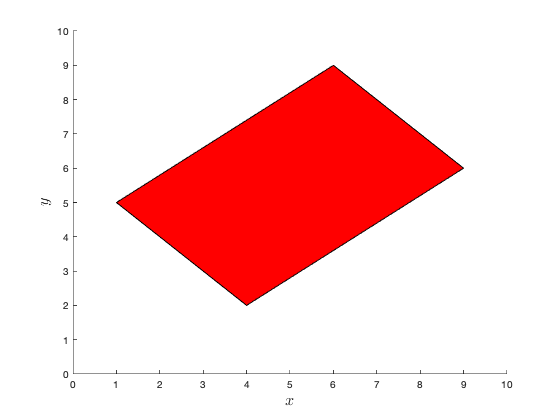

clf % clear the figure

x = [ 1, 4, 9, 6 ];
y = [ 5, 2, 6, 9 ];

patch(x, y, 'r')

axis([ 0, 10, 0, 10 ])

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

**Example 17**

The MATLAB code below plots two polygons (a red rectangle and a yellow triangle) on the same figure. Enter it into the code cell below and run the live script.

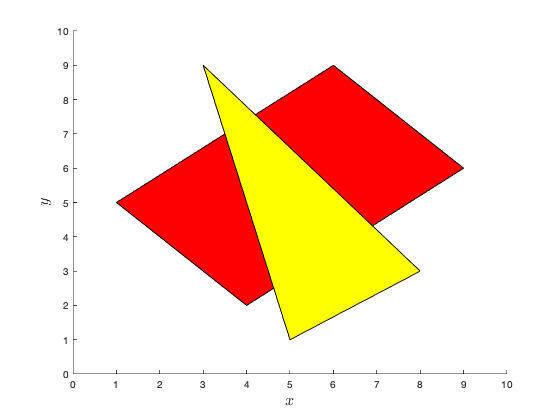

clf

x1 = [ 1, 4, 9, 6 ];  % 1st polygon vertex co-ordinates
y1 = [ 5, 2, 6, 9 ];
x2 = [ 5, 8, 3 ];     % 2nd polygon vertex co-ordinates
y2 = [ 1, 3, 9 ];

patch(x1, y1, 'r')    % plot 1st polygon
patch(x2, y2, 'y')    % plot 2nd polygon

axis([ 0, 10, 0, 10 ])

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

### The RGB colour model

The RGB colour model combines the three primary colours **R**ed, **G**reen and **B**lue to produce colours in the visibly spectrum ([RGB color model wikipedia article](https://en.wikipedia.org/wiki/RGB_color_model)). MATLAB uses a three-element vector to define the amount of the three primary colours used where each element is a number in the range $[0,1]$. For example

**Example 18**

The MATLAB code below plots a purple hexagon. Enter it into the code cell below and run the live script.

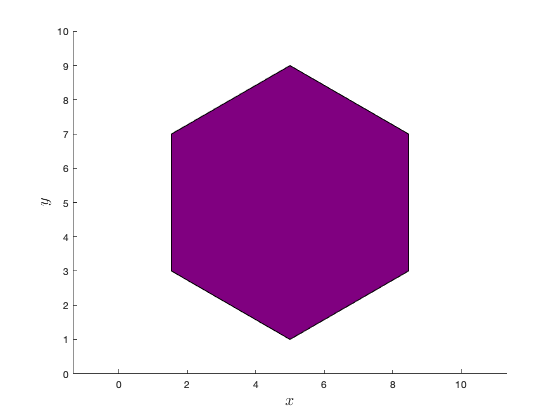

clf

cx = 5;                                 % co-ordinates of the centre of the hexagon
cy = 5;
r = 4;                                  % distance from centre to each vertex
dtheta = 2 * pi / 6;                    % change in angle between vertices
theta = 0.5 * dtheta : dtheta : 2 * pi; % array of angles

x = cx + r * cos(theta);
y = cy + r * sin(theta);

patch(x, y, [0.5, 0, 0.5])

axis ([0, 10, 0, 10 ])
axis equal

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

### Exercise 6

10. Use the `patch` command plot a series of [regular polygons](https://en.wikipedia.org/wiki/Regular_polygon) of different sizes, positions and colours.

Hint: Look at the code from Example 15. 

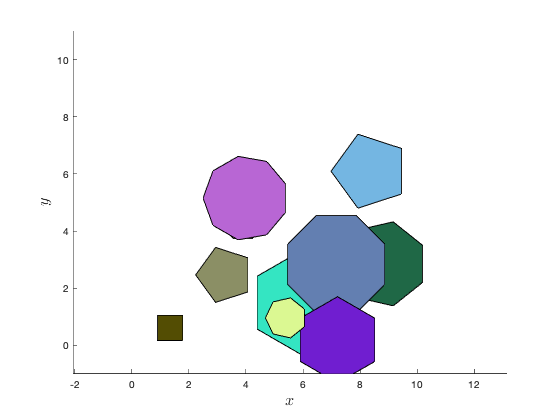

clf

npoly = 10;                     % number of polygons
for i = 1 : npoly
    
    % Randomize polygon
    cx = 10 * rand;             % random centre co-ordinates [0, 10]
    cy = 10 * rand;
    r = 0.5 + 1.5 * rand;       % random radius [0.5, 2]
    nsides = 2 + randi(7);      % random number of sizes in range [3, 8]
    dtheta = 2 * pi / nsides;
    theta = 0.5*dtheta : dtheta : 2*pi;
    
    % Calculate x and y arrays
    x = cx + r * cos(theta);
    y = cy + r * sin(theta);
    
    % Plot polygon
    patch(x, y, rand(1, 3))
    
end

axis([-1, 11, -1, 11])
axis equal

xlabel('$x$', 'FontSize', 16, 'Interpreter', 'latex')
ylabel('$y$', 'FontSize', 16, 'Interpreter', 'latex')

## Image plots

***Image*** plots (also known as ***raster plots***) are plots which consist of an array of small squares called ***pixels***. In MATLAB image plots can be produced using the `image` and `imagesc` commands.

Where `img` is an array of pixel data. The `image` command assumes that the data is formatted so that each pixel has components for the red, green and blue colours for the RGB colour model (known as **True Colors **- see diagram below). 

The `imagesc` command assumes the data is formatted so that each pixel is represented by a single number (known as **Indexed Colors**). The colour of each pixel is scaled based on the values in the data array and applied using a [colormap](https://uk.mathworks.com/help/matlab/ref/colormap.html).

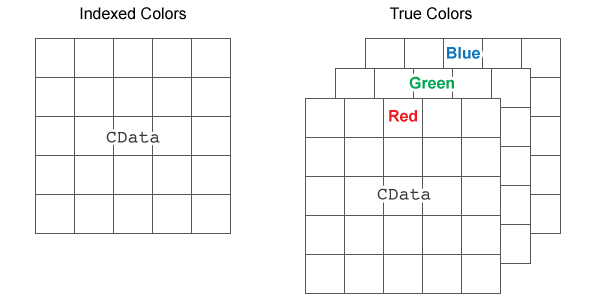

**Example 19**

The following commands generate a random array of $10\times 10$ pixels and plots them using the `imagesc` command. (the `axis equal tight` command ensures that the pixels are represented as squares and the vertical axis counts up from the bottom). Enter them into the code cell below and run the live script.

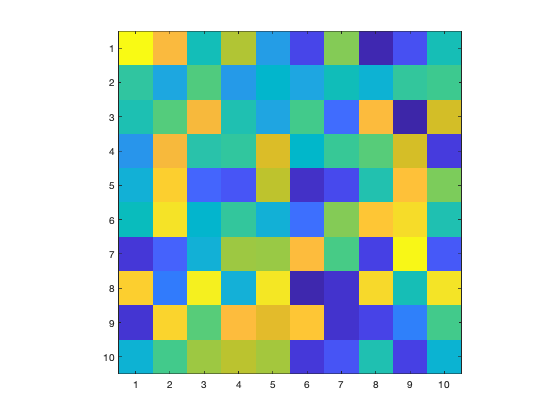

img = rand(10, 10);

imagesc(img)

axis equal tight

### **Importing an image file into an array**

We can read in an image file into an array using the `imread` command ([help page](https://uk.mathworks.com/help/matlab/ref/imread.html))

Where `filename` is the name of the image file. This allows us to perform image manipulation operations on the image. Most common image types such as jpegs, pngs, tifs are supported. The information for the image is stored in the array `X` which is an $m\times n \times 3$ where $m$ and $n$ are the number of pixels in the vertical and horizontal direction. Each pixel has 3 values which correspond to the amount of red, green and blue as used in the RGB colour model.

**Example 20**

The following commands read in the data for the image file `yellowlily.jpg` which comes with MATLAB and plots the data using the `image` command. Enter them into the code cell below and run the live script.

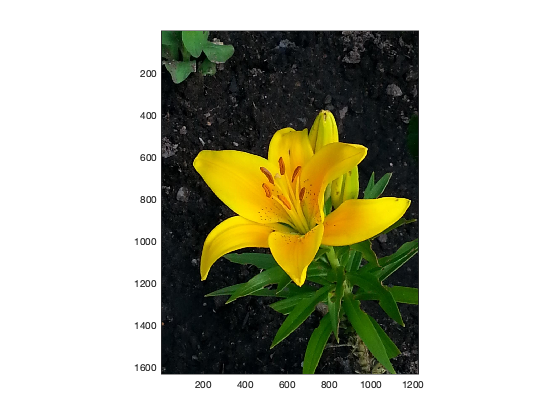

img = imread('yellowlily.jpg');

image(img)

axis equal tight

[Nx, Ny, ~] = size(img);
fprintf([ 'The image is made up of %1i pixels in the horizontal direction' ...
    ' and %1i pixels in the vertical direction.'], Nx, Ny)

The image is made up of 1632 pixels in the horizontal direction and 1224 pixels in the vertical direction.

### Exercise 7

11. Use two nested `for` loops to generate an $11\times 11$ array `img` where the value of each element is the distance from the centre element, i.e.,


$$[\text{img}]_{ij} = \sqrt{(i - 6)^2 + (j - 6)^2}$$
 

Plot `img` using the `imagesc` command.

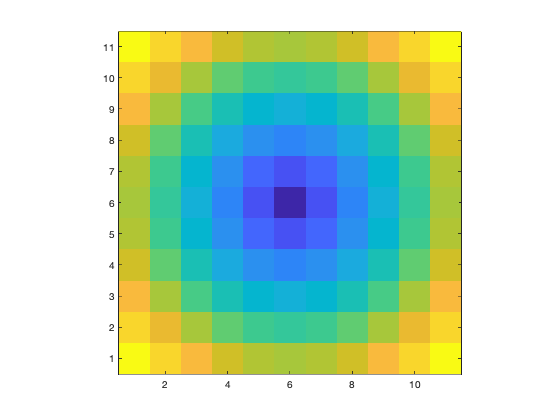

img = zeros(11, 11);
for i = 1 : 11
    for j = 1 : 11
        img(i, j) = sqrt((i - 6)^2 + (j - 6)^2);
    end
end

imagesc(img)

axis xy equal tight

12. Download the photograph of the central libray from the Moodle area for this unit and save it to the same directory where this live script is stored. Read in the data into an array and plot the array using the `image` command. What is the size of the image?

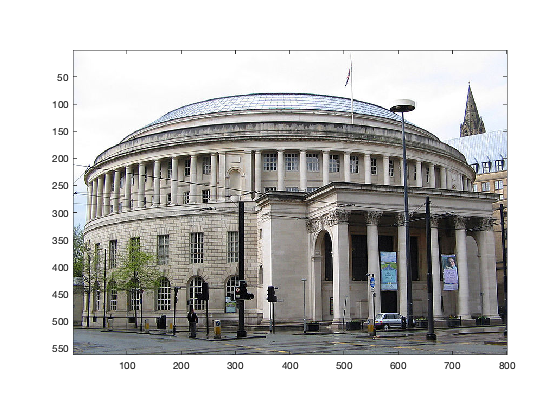

img = imread('central_library.jpg');

image(img)

axis equal tight

[height, width, ~] = size(img);
fprintf('The image has a height of %1i pixels and a width of %1i pixels.', ...
    height, width)

The image has a height of 562 pixels and a width of 800 pixels.